# ME 535 Assignment 8 - Fall 2018

# Debabrata Auddya 

**Question 6.4: Examine the continuity between the two patches. Render these two patches and their control nets**

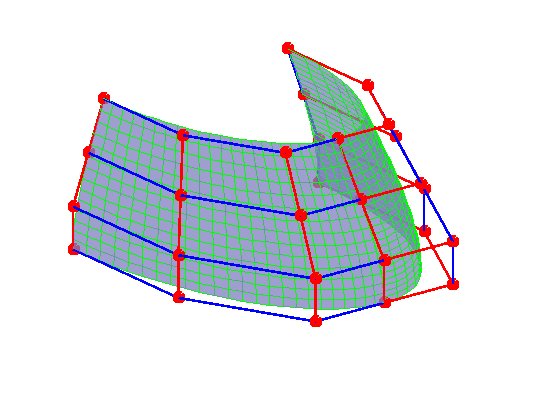

clear all, close all;

% control points A for a degree 3 * 3 patch
 P =  [1.5 0 2.4; 1.5 -0.84 2.4; 0.84 -1.5 2.4; 0 -1.5 2.4;
       1.75 0 1.875; 1.75 -0.98 1.875; 0.98 -1.75 1.875; 0 -1.75 1.875;
       2 0 1.35; 2 -1.12 1.35; 1.12 -2 1.35; 0 -2 1.35;
       2 0 0.9; 2 -1.12 0.9; 1.12 -2 0.9; 0 -2 0.90];  % Example problem
 nr = 4;
 nc = 4;
 
 P2 = [0 -1.5000 2.4000;0 -1.7500 1.8750;0 -2.0000 1.3500;0 -2.0000 0.9000;
      -0.8400 -1.5000 2.4000; -0.9800 -1.7500 1.8750;-1.1200 -2.0000 1.3500; -1.1200 -2.0000 0.9000; 
      -1.5000 -0.8400 2.4000; -1.7500 -0.9800 1.8750; -2.0000 -1.1200 1.3500; -2.0000 -1.1200 0.9000;
      -1.5000 0 2.4000; -1.7500 0 1.8750; -2.0000 0 1.3500; -2.0000 0 0.9000];
 
% surface evaluation
u = 1/2.; v = 1/2.;
tQ = deCasteljauSurf(P,nr, nc, u, v);
tQ2 = deCasteljauSurf(P2,nr, nc, u, v);


%number of sampled points
snr = 25; % number of sampled points in row (in u direction)
snc = 15; % number of sampled points in col (in v direction)
hold on;
Q = bezierSurf(P, nr, nc, snr, snc);
Q2 = bezierSurf(P2, nr, nc, snr, snc);
%plot the surface
bezierSurfPlot(P, Q, nr, nc, snr, snc);
bezierSurfPlot(P2, Q2, nr, nc, snr, snc);
view(3)

axis off;

disp('The surfaces are C1 continuous')

The surfaces are C1 continuous


**Question 6.5 : Cubic Bezier approximation of a circle:**

**a. Identify the four control points for  the cubic Bezier approximation of the quarter circle**

**Solution: **$q_0 = (\frac{x}{2}, 1) , q_1 = (1 , \frac{y}{2})\\
q_2 = (\frac{x+1}{2} , \frac{y+1}{2})\\
q_0,q_1,q_2 \ \text{represent the first set of interpolated points using the deCasteljau algorithm}\\
r_0 = \Bigg (\frac{\frac{x+1}{2} + \frac{x}{2} }{2},  \frac{\frac{y+1}{2} + 1}{2} \Bigg) \\
r_1 =  \Bigg (\frac{\frac{x+1}{2} + 1 }{2},  \frac{\frac{y+1}{2} + \frac{y}{2}}{2} \Bigg) \\
r_0, r_1 \ \text{second set of interpolated points}\\ 
r = \frac{r_0 + r_1}{2}\\
\text{r is the approximated point using the same algorithm} \\
\text{Since}\ c(0.5,0.5) =\Big ( \frac{\sqrt{2}}{2}, \frac{\sqrt{2}}{2} \Big ), \\
\text{The value of x and y can be found out as}\\
3x + 4 = 4\sqrt{2}\\
x = \frac{4 (\sqrt{2} - 1)}{3} = 0.5522\\
\text{Similarly} y = 0.5522 \\
\text{Hence the control points are:}\\
p_0 = (0,1)\\
p_1 = (0.5522,1)\\
p_2 = (1,0.5522)\\
p_3 = (1,0)
$

**b. Find out the maximum discrepancy between the approximated quarter circle and the exact quarter circle**

clear all;
close all;
u = 0:0.01:1;
y = 0*(1 - u).^3 + 0.5522*3.*u.*(1-u).^2 + 1*3*(1-u).*u.^2 + 1*u.^3;
x = 1*(1 - u).^3 + 1*3.*u.*(1-u).^2 + 0.5522*3*(1 - u).*u.^2 + 0*u.^3;
c = cos(u*pi/2);
d = sin(u*pi/2);
z = sqrt((x -c).^2 + (y - d).^2);
disp('The maximum value of discrepancy')

The maximum value of discrepancy


max(z)

ans = 0.0073

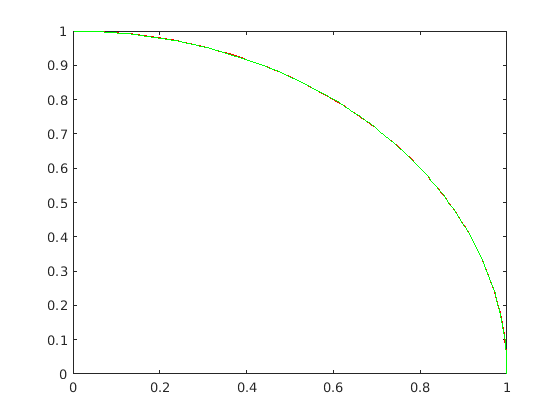

for i=1:length(z)
    if (z(i) == max(z))
        break;
    end
end
plot(x,y,'r')
hold on
plot(c,d,'g')

disp('The value of u at which max discrepancy occurs')

The value of u at which max discrepancy occurs


u(i)

ans = 0.2000

**Question 6.6: Display its six components (lid, rim, body, handle, spout, bottom) separately.**

**Component 1: Lid**

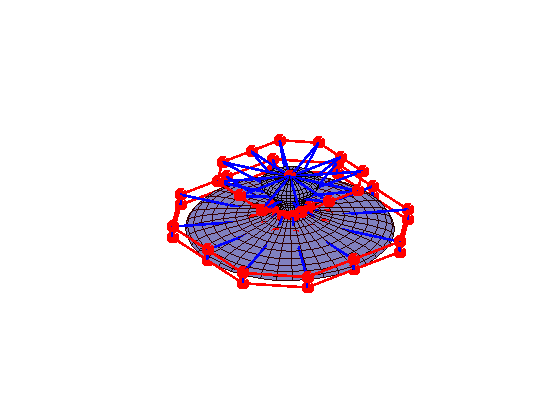

clear;
N = 10; % number of intervals in u and v directions

tp32BezierPatch; 
% load data "vert" (3D coordinates of CPs) 
% "quad" (a collection of patches, each with 16 CP indices)

quad2 = cat(3,[
                   % body                      
                      13  14  15  16 ;  49  50  51  52 ;  53  54  55  56 ;  57  58  59  60 ] , [
                      16  26  27  28 ;  52  61  62  63 ;  56  64  65  66 ;  60  67  68  69 ] );
quad_rim = cat(3,[ 
                   % rim
                       1   2   3   4 ;   5   6   7   8 ;   9  10  11  12 ;  13  14  15  16 ] , [
                       4  17  18  19 ;   8  20  21  22 ;  12  23  24  25 ;  16  26  27  28 ] , [
                      19  29  30  31 ;  22  32  33  34 ;  25  35  36  37 ;  28  38  39  40 ] , [
                      31  41  42   1 ;  34  43  44   5 ;  37  45  46   9 ;  40  47  48  13 ]);
quad_body = cat(3,[
                   % body                      
                      13  14  15  16 ;  49  50  51  52 ;  53  54  55  56 ;  57  58  59  60 ] , [
                      16  26  27  28 ;  52  61  62  63 ;  56  64  65  66 ;  60  67  68  69 ] , [
                      28  38  39  40 ;  63  70  71  72 ;  66  73  74  75 ;  69  76  77  78 ] , [
                      40  47  48  13 ;  72  79  80  49 ;  75  81  82  53 ;  78  83  84  57 ] , [
                      57  58  59  60 ;  85  86  87  88 ;  89  90  91  92 ;  93  94  95  96 ] , [
                      60  67  68  69 ;  88  97  98  99 ;  92 100 101 102 ;  96 103 104 105 ] , [
                      69  76  77  78 ;  99 106 107 108 ; 102 109 110 111 ; 105 112 113 114 ] , [
                      78  83  84  57 ; 108 115 116  85 ; 111 117 118  89 ; 114 119 120  93 ] );
                  
quad_handle = cat(3,[
                   % handle
                     121 122 123 124 ; 125 126 127 128 ; 129 130 131 132 ; 133 134 135 136 ] , [
                     124 137 138 121 ; 128 139 140 125 ; 132 141 142 129 ; 136 143 144 133 ] , [
                     133 134 135 136 ; 145 146 147 148 ; 149 150 151 152 ;  69 153 154 155 ] , [
                     136 143 144 133 ; 148 156 157 145 ; 152 158 159 149 ; 155 160 161  69 ] );                  
quad_spout = cat(3,[
                   % spout
                     162 163 164 165 ; 166 167 168 169 ; 170 171 172 173 ; 174 175 176 177 ] , [
                     165 178 179 162 ; 169 180 181 166 ; 173 182 183 170 ; 177 184 185 174 ] , [
                     174 175 176 177 ; 186 187 188 189 ; 190 191 192 193 ; 194 195 196 197 ] , [
                     177 184 185 174 ; 189 198 199 186 ; 193 200 201 190 ; 197 202 203 194 ]);
quad_lid = cat(3,[
                   % lid
                     204 204 204 204 ; 207 208 209 210 ; 211 211 211 211 ; 212 213 214 215 ] , [
                     204 204 204 204 ; 210 217 218 219 ; 211 211 211 211 ; 215 220 221 222 ] , [
                     204 204 204 204 ; 219 224 225 226 ; 211 211 211 211 ; 222 227 228 229 ] , [
                     204 204 204 204 ; 226 230 231 207 ; 211 211 211 211 ; 229 232 233 212 ] , [
                     212 213 214 215 ; 234 235 236 237 ; 238 239 240 241 ; 242 243 244 245 ] , [
                     215 220 221 222 ; 237 246 247 248 ; 241 249 250 251 ; 245 252 253 254 ] , [
                     222 227 228 229 ; 248 255 256 257 ; 251 258 259 260 ; 254 261 262 263 ] , [
                     229 232 233 212 ; 257 264 265 234 ; 260 266 267 238 ; 263 268 269 242 ]);
quad_bottom = cat(3,[
                   % bottom
                     270 270 270 270 ; 279 280 281 282 ; 275 276 277 278 ; 271 272 273 274 ] , [
                     270 270 270 270 ; 282 289 290 291 ; 278 286 287 288 ; 274 283 284 285 ] , [
                     270 270 270 270 ; 291 298 299 300 ; 288 295 296 297 ; 285 292 293 294 ] , [
                     270 270 270 270 ; 300 305 306 279 ; 297 303 304 275 ; 294 301 302 271 ]);

quad_test = cat(3,[
                   % rotation
                      57  58  59  60 ;  85  86  87  88 ;  89  90  91  92 ;  93  94  95  96 ] , [
                      60  67  68  69 ;  88  97  98  99 ;  92 100 101 102 ;  96 103 104 105 ] , [
                      69  76  77  78 ;  99 106 107 108 ; 102 109 110 111 ; 105 112 113 114 ] , [
                      78  83  84  57 ; 108 115 116  85 ; 111 117 118  89 ; 114 119 120  93 ] , [
                     270 270 270 270 ; 279 280 281 282 ; 275 276 277 278 ; 271 272 273 274 ] , [
                     270 270 270 270 ; 282 289 290 291 ; 278 286 287 288 ; 274 283 284 285 ] , [
                     270 270 270 270 ; 291 298 299 300 ; 288 295 296 297 ; 285 292 293 294 ] , [
                     270 270 270 270 ; 300 305 306 279 ; 297 303 304 275 ; 294 301 302 271 ]);
DisplayCP = true;

quads = quad_lid;  % rotation  
%quads = quad_spout;   % tube               
%quads = quad_handle;   % tube               
%quads = quad_body;   % rotation               
%quads = cat(3, quad_body, quad_spout);   % for C1 inspection               
%quads = quad2; 


CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Component 2: Rim** 

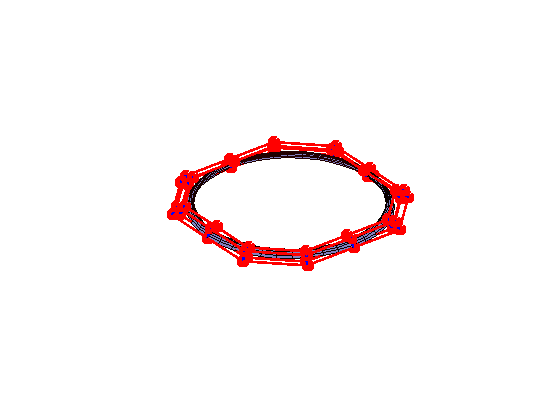

quads = quad_rim;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Component 3: Body**

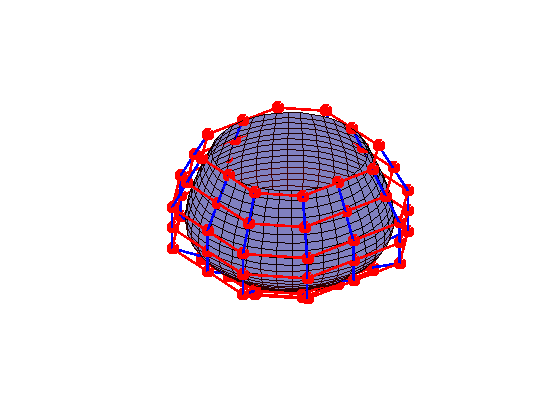

quads = quad_body;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Component 4: Handle**

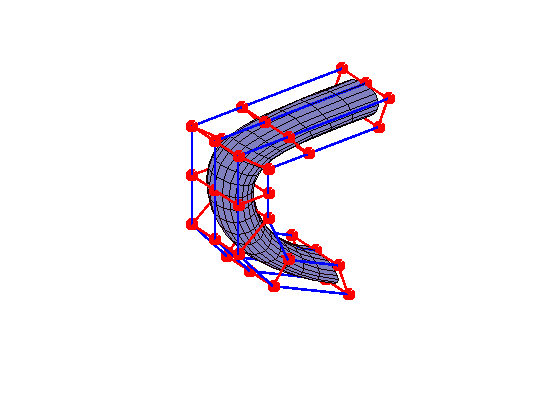

quads = quad_handle;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Component 5: Spout **

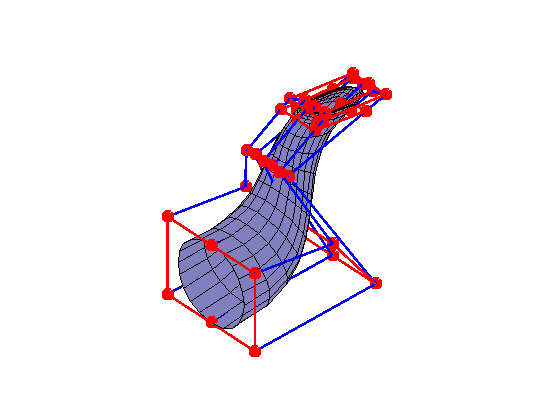

quads = quad_spout;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Component 6: Bottom **

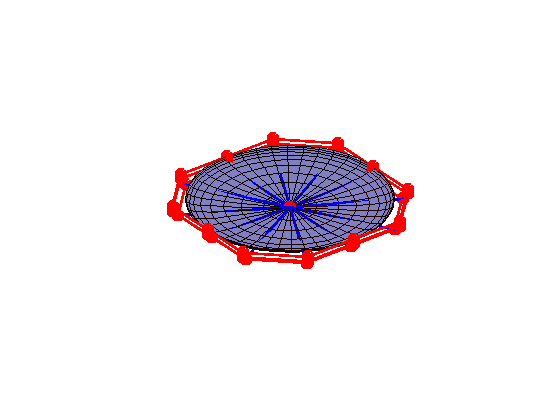

quads = quad_bottom;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
view(3)
hold off;

**Question 6.6b: Smoothness order in the handle and the body**

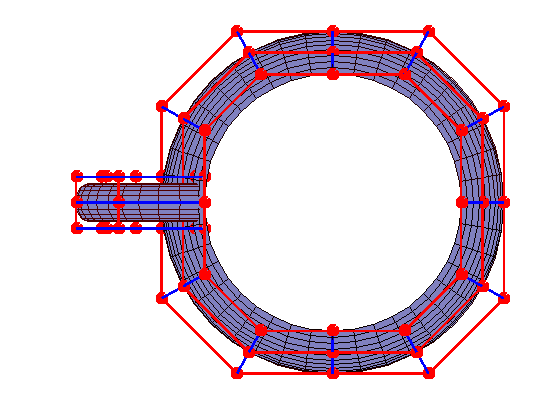

quads = cat(3, quad_body, quad_handle); 
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
hold off;

disp('We can see from inspection that the continuity between the handle and the body is C0');

We can see from inspection that the continuity between the handle and the body is C0


disp('Meaning the curve is just continuous, there is no derivative continuity between them');

Meaning the curve is just continuous, there is no derivative continuity between them


disp('It isnt C1 continuous')

It isnt C1 continuous


**Question 6.6c: Use bicubic Bézier patches to model a rotational object of your choice. Submit control points**

**coordinates and connectivity in the same file format as the provided data file.**

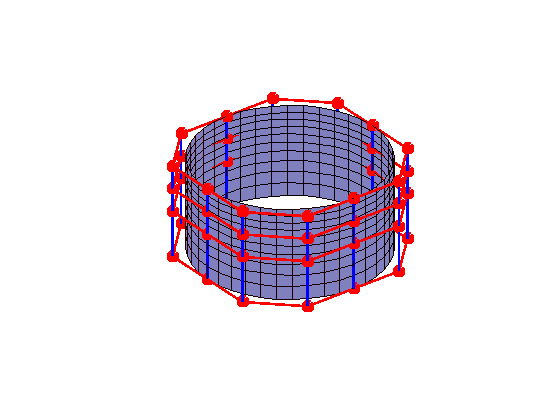

testRotationPatch;
quads = quads_rot;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
hold off;
view(3)

**Question 6.6d: Use bicubic Bézier patches to model a three-dimensional tubular object of your choice. Submit control points coordinates and connectivity in the same file format as the provided data file.**

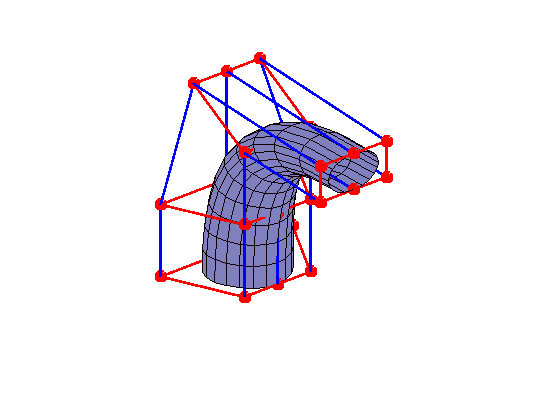

testTubePatch;
quads = quads_tube;
CtrlPt=zeros(4,4,3); % CP for one bicubic patch
xyz=zeros((N+1),(N+1),3);
bu=zeros(1, 4);
bv=zeros(1, 4);
figure(1)
clf; hold on;
axis equal;
axis off;
for k=1:size(quads,3)
    % get k-th patch's control points
    for i=1:4
        for j=1:4
            for l=1:3
                CtrlPt(i,j,l)=verts(quads(i,j,k),l);
            end
        end
    end
    
    % compute (N+1)*(N+1) surface points
    for i=1:N+1
        for j=1:N+1
            u= 0.0 + (i-1)*1.0/N;
            v= 0.0 + (j-1)*1.0/N;
            u_ = 1.0 - u;
            u2=u*u;
            % cubic Bernstein polynomials in u
            bu(1)=u*u2;
            bu(2)=3.0*u2*u_;
            bu(3)=3.0*u*u_*u_;
            bu(4)=u_*u_*u_;
            v_ = 1.0 - v;
            v2=v*v;
            % cubic Bernstein polynomials in u
            bv(1)=v*v2; bv(2)=3.0*v2*v_; bv(3)=3.0*v*v_*v_; bv(4)=v_*v_*v_;
            % patch evaluation for x, y, and z
            for kk=1:3
                tmp = 0.0;
                % add 4*4 control points' contribution
                for ii = 1:4
                    for jj = 1:4
                        tmp = tmp + bu(ii) * bv(jj) * CtrlPt(ii,jj,kk);
                    end
                end
                xyz(i,j,kk) = tmp;
            end
        end
    end
    % plot the patch
    p = surf(xyz(:,:,1),xyz(:,:,2),xyz(:,:,3));
    p.EdgeColor=k*[1,0,0]/32; %'green'; %0.5*[1 1 1 ]
    p.FaceAlpha=1; %0.75;
    p.FaceColor = [0.5 0.5 0.75];
    
    % plot the control net
    % CtrlPt: 4*4*3
    % reshape(CtrlPt,[16,3]) to get 16*3 CP representation.
    if DisplayCP == true
        for i=1:4
         plot3(CtrlPt(i,:,1),CtrlPt(i,:,2), CtrlPt(i,:,3),'-ro', 'linewidth',2,'MarkerFaceColor', 'r', 'MarkerSize',8);
        end

        for i=1:4
         plot3(CtrlPt(:,i,1),CtrlPt(:,i,2), CtrlPt(:,i,3),'-b', 'linewidth',2);
        end
    end
    
    %camlight
end
% shading interp
% colormap(bone);
%camlight
hold off;
view(3)